SK = slam_kalman()

SK =   slam_kalman with properties:

           state: [15×1 double]
             cov: [15×15 double]
     p_tag_front: []
      p_tag_back: []
               T: []
     UWB_cov_mat: []
     IMU_cov_mat: []
    odom_cov_mat: []
     process_cov: []



SK.T = 1/15;
SK.p_tag_front = [0.2; 0];
SK.p_tag_back  = [-0.2; 0];
SK.odom_cov_mat = eye(2)*0.1.^2;
SK.UWB_cov_mat = eye(8)*0.1.^2;
SK.IMU_cov_mat = eye(2)*0.1.^2;
SK.process_cov = diag([0 0 0 0.2 0.2 1]).^2;

% meas_UWB = [dist_front_history(:,1); dist_back_history(:,1)];
% [state_c, cov_c] = LK.multi_meas(meas_UWB, [])

kalman_state_hist = [];

for n = 1:width(dist_front_history)
    meas_UWB = [dist_front_history(:,n); dist_back_history(:,n)];
    meas_IMU = IMU_history(:,n);
    meas_odom = odom_history(:,n);
    [state_c, cov_c] = SK.multi_meas(meas_UWB, meas_IMU, meas_odom);
    kalman_state_hist(:,n) = state_c;

end


s = kalman_state_hist(:,end)

s =     7.0198
    3.3441
    0.1183
    0.0206
    1.3630
    5.6969
   -3.7723
    7.8892
    5.6352
    8.6788


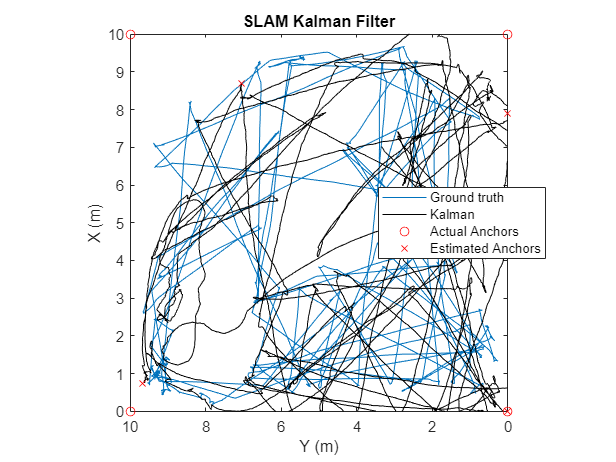


anchor_mat_p = [0            s(8) s(10) s(13)
                            0            0            s(11) s(14)
                            s(7) s(9) s(12) s(15)];

plot(robot_state_history(1,:), robot_state_history(2,:)); hold on
plot(kalman_state_hist(1,:), kalman_state_hist(2,:),'k'); 
plot(anchor_mat(1,:), anchor_mat(2,:), 'ro'); 
plot(anchor_mat_p(1,:), anchor_mat_p(2,:), 'rx'); hold off
axis equal
view(-90,90);
xlim([0 10])
ylim([0 10])

xlabel("X (m)")
ylabel("Y (m)")
title("SLAM Kalman Filter")

legend(["Ground truth", "Kalman", "Actual Anchors", "Estimated Anchors"], "Location","east")